
combinedTable = vertcat(Final_Cycle, Final_Run, Final_Walk);
combinedTable = timetable2table(combinedTable, "ConvertRowTimes", false)

combinedTable = 922×10 table
    latitude    longitude    altitude    speed     AvgX       AvgY      AvgZ     Activity     HeartRate    HeartrateMax
    ________    _________    ________    _____    _______    ______    ______    _________    _________    ____________

     1.3434      103.68       41.226     2.169     2.7333    4.6321    7.8784    {'cycle'}     97.927         107.61   
     1.3435      103.68         41.2     2.169    0.51132    4.5787    8.3323    {'cycle'}     97.983         107.61   
     1.3432      103.68       41.299     2.169     1.9171     3.007    8.4754    {'cycle'}      98.15         107.61   
     1.3429      103.68       



cv = cvpartition(size(combinedTable,1),'HoldOut',0.3);
idx = cv.test;
% Separate to training and test data
dataTrain = combinedTable(~idx,:);
dataTest  = combinedTable(idx,:);


classificationLearner


yfit = trainedModel.predictFcn(dataTest)

yfit = 276×1 cell array
    {'cycle'}
    {'cycle'}
    {'cycle'}
    {'cycle'}
    {'cycle'}
    {'cycle'}
    {'cycle'}
    {'cycle'}
    {'cycle'}
    {'walk' }
    {'cycle'}
    {'cycle'}
    {'cycle'}
    {'cycle'}
    {'cycle'}
    {'cycle'}
    {'cycle'}
    {'cycle'}
    {'cycle'}
    {'cycle'}
    {'cycle'}
    {'cycle'}
    {'cycle'}
    {'cycle'}
    {'walk' }
    {'walk' }
    {'walk' }
    {'cycle'}
    {'cycle'}
    {'cycle'}


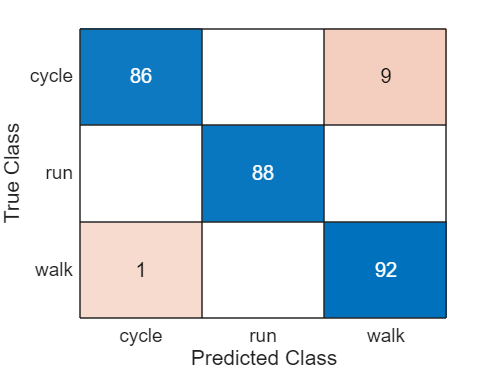

cm =   ConfusionMatrixChart with properties:

    NormalizedValues: [3×3 double]
         ClassLabels: {3×1 cell}

  Show all properties


cm = confusionchart(dataTest.Activity,yfit)